**Approach 1: Using Newton-Raphson method for N variables.**

This methos is used to solve a system of non-linear equations using an initial guess and updating the solution in each step until a desired accuracy is achieved.

% Defining the MNA equation
G = [0.02 -0.02 0 1 ; -0.02 0.02 0 0 ; 0 0 0.001 0 ; 1 0 0 0];
C = [0 0 0 0 ; 0 0 0 0 ; 0 0 0.0001 0 ; 0 0 0 0];

Is = 10^-13; % diode current
VT = 0.025; % thermal voltage

A = 5; % Amplitude
frequency = 60;
w = 2 * pi * frequency; % angular frequency (omega)

t0 = 0;
dt = 0.0001;%Sample Time Step
t = t0:dt:0.5;
y = zeros(size(t));

Vsc = zeros(length(t),1);%matrix to store voltage values
B = zeros(4,length(Vsc)); % B is a function of time and so the matrix contains the B vector at every time step. 
    for i=1:length(Vsc)
        Vsc(i,1) = A*sin(w*t(1,i));
        B(:,i) = [0;0;0;Vsc(i,1)];
    end

% Displaying values of GCB matrices generated
disp("The matrix G is:")

The matrix G is:


disp(G)

    0.0200   -0.0200         0    1.0000
   -0.0200    0.0200         0         0
         0         0    0.0010         0
    1.0000         0         0         0



disp("The matrix C is:")

The matrix C is:


disp(C)

   1.0e-04 *

         0         0         0         0
         0         0         0         0
         0         0    1.0000         0
         0         0         0         0



disp("The matrix B is:")

The matrix B is:


disp(B)

  Columns 1 through 17

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1885    0.3766    0.5643    0.7511    0.9369    1.1214    1.3042    1.4852    1.6641    1.8406    2.0145    2.1856    2.3535    2.5181    2.6791    2.8363

  Columns 18 through 34

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0     

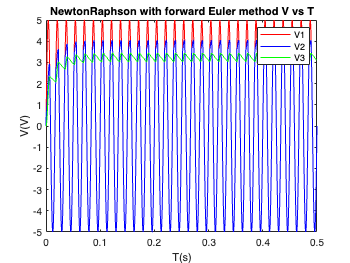



a = G + C/dt; % forward euler method
X_ni=zeros(4,1);
X_ni_store=zeros(4,length(t));
Xguess=[0.4;0.1;-0.1;1e-4];

for i=1:length(t)-1
    j=i+1;
    b=B(:,j)+C/dt*X_ni-FunctionValue(X_ni(2), X_ni(3));
    X_ni_store(:,j)=NewtonRaphson(Xguess,a,b);
    X_ni=X_ni_store(:,j);
    Xguess=X_ni;
end

plot(t,X_ni_store(1,:),'r', DisplayName='V1');
hold on
plot(t,X_ni_store(2,:),'b', DisplayName='V2');
hold on
plot(t,X_ni_store(3,:),'g', DisplayName='V3');

xlabel("T(s)");
ylabel("V(V)");
legend;
title('NewtonRaphson with forward Euler method V vs T')
hold off

function [X_NR] = NewtonRaphson(Xguess,a,b) % newton raphson method with 3 arguments
    
    tol=1e-6; % tolerance
    Function = a * Xguess + FunctionValue(Xguess(2,1),Xguess(3,1)) - b;  
    Function_derivative = JacobianValue(Xguess(2,1),Xguess(3,1)) + a; 
    dX = Function_derivative \ Function; 
    
    Xguess = Xguess - dX; % Guess update 
    
    count = 1; % To keep track of the number of Newton Raphson Iterations. 
   
    while norm(dX) > tol % while norme is greater than tolerance

        Function = a*Xguess + FunctionValue(Xguess(2,1),Xguess(3,1)) - b; 
        Function_derivative = JacobianValue(Xguess(2,1),Xguess(3,1)) + a;  
        dX = Function_derivative \ Function;
       
        Xguess = Xguess - dX; % Guess Update(2) 
        count = count+1;
    end
    X_NR = Xguess; % Update final value of X_NR
end

function [eval] = FunctionValue (V2, V3) % evaluate function values for the given equations
    Is = 10^-13; % diode current
    VT = 0.025; % thermal voltage
    Vdiff = V2 - V3;

    eval = zeros(4, 1);
    eval(2, 1) = Is * (exp((Vdiff) / VT) - 1);
    eval(3, 1) = -Is * (exp((Vdiff) / VT) - 1);
end

function [J] = JacobianValue(V2, V3) % evaluates jacobian values for the given equations
    Is = 10^-13; % diode current
    VT = 0.025; % thermal voltage
    
    J = zeros(4, 4);

    Vdiff = V2 - V3;
    J(2, 2) = (Is/VT) * (exp((Vdiff)/VT));
    J(2, 3) = -(Is/VT) * (exp((Vdiff)/VT));
    J(3, 2) = -(Is/VT) * (exp((Vdiff)/VT));
    J(3, 3) = (Is/VT) * (exp((Vdiff)/VT));
    J(4, 2) = 0;
    J(4, 3) = 0;
end